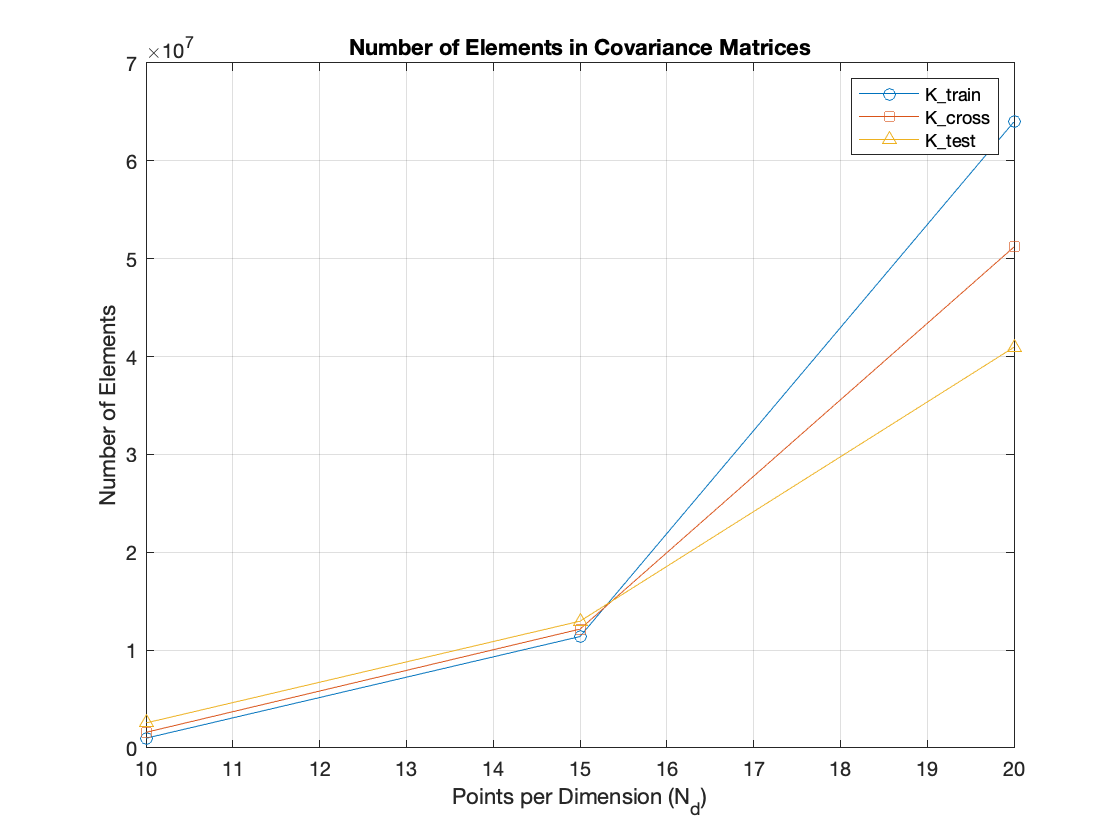

clear all;
clc;
close all;

Nd = [10, 15, 20];
hyp = [0.05, 1];

% Initialize arrays to store numels
numel_K_train = zeros(1, length(Nd));
numel_K_cross = zeros(1, length(Nd));
numel_K_test = zeros(1, length(Nd));

for i = 1:length(Nd)
    [X, y, Xstar] = getdata(Nd(i), hyp);
    [N, D] = size(X);
    M = size(Xstar, 1);
    
    % Compute covariance matrices
    K_train = zeros(N, N);
    K_cross = zeros(M, N);
    K_test = zeros(M, M);
    
    % Store the number of elements in each matrix
    numel_K_train(i) = numel(K_train);
    numel_K_cross(i) = numel(K_cross);
    numel_K_test(i) = numel(K_test);
end

% Plotting the results
figure;
plot(Nd, numel_K_train, '-o', 'DisplayName', 'K\_train');
hold on;
plot(Nd, numel_K_cross, '-s', 'DisplayName', 'K\_cross');
plot(Nd, numel_K_test, '-^', 'DisplayName', 'K\_test');
hold off;

% Customize plot
xlabel('Points per Dimension (N_d)');
ylabel('Number of Elements');
title('Number of Elements in Covariance Matrices');
legend;
grid on;